# Assessment 3A

H00368671

**Task 1:**

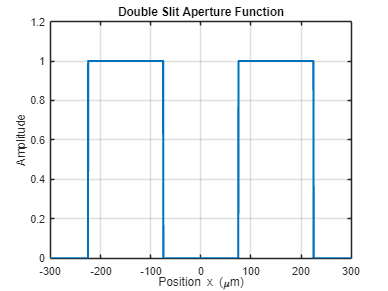

clear all; close all; clc;

% Define spatial domain
N = 2048;            
L = 1e-3;            
dx = L / N;          
x = -L/2 : dx : L/2 - dx;   

% Define parameters for slits
a = 150e-6;           
d = 300e-6;          

% Define aperture function
f = ((abs((x + d/2)/a) <= 0.5) + (abs((x - d/2)/a) <= 0.5));

% Plot the aperture function
figure;
plot(x*1e6, f, 'LineWidth', 2);
xlabel('Position x (\mum)');
ylabel('Amplitude');
title('Double Slit Aperture Function');
grid on;
ylim([0 1.2])
xlim([-300 300])

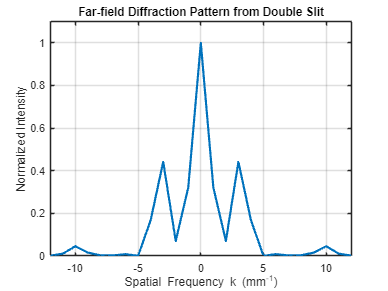


% Compute the Fourier Transform
F = fftshift(fft(f));

% Compute the spatial frequency coordinate k
dk = 1 / (N * dx);                   
k = (-N/2 : N/2 - 1) * dk;           

% Compute the intensity pattern 
I = abs(F).^2;                       

% Normalize intensity for plotting
I = I / max(I);

% Plot the intensity pattern
figure;
plot(k*1e-3, I, 'LineWidth', 2);     
xlabel('Spatial Frequency k (mm^{-1})');
ylabel('Normalized Intensity');
title('Far-field Diffraction Pattern from Double Slit');
grid on;
xlim([-12, 12])
ylim([0 1.1])

**Task 2:**

% Read audio file 
[audioData, fs] = audioread('Kid_Laugh.mp3');

if size(audioData,2) == 2
    audioData = mean(audioData, 2);
end

% Play the original audio
disp('Playing original audio...');

Playing original audio...


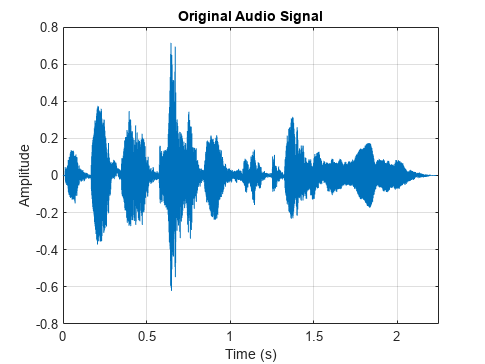

sound(audioData, fs);
pause(length(audioData)/fs + 1); 

% Plot the time-domain signal
t = (0:length(audioData)-1) / fs; 
figure;
plot(t, audioData);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Audio Signal');
grid on;
xlim([0 2.25])

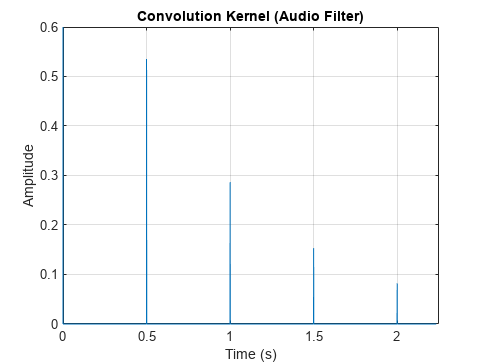


% Generate the convolution kernel 
% Parameters for the filter
delay = 0.5;       
decay = 0.8;       
filterLength = length(audioData); 

% Initialize the convolution kernel
convKernel = zeros(filterLength, 1);

% Number of samples corresponding to the delay
delaySamples = round(delay * fs);

% Create the convolution kernel with decaying echoes
numEchoes = floor(filterLength / delaySamples);
for n = 0:numEchoes
    idx = n * delaySamples + 1;
    if idx <= filterLength
        convKernel(idx) = exp(-n * delay / decay);
    end
end

% Plot the convolution kernel
t_conv = (0:length(convKernel)-1) / fs; 
figure;
plot(t_conv, convKernel);
xlabel('Time (s)');
ylabel('Amplitude');
title('Convolution Kernel (Audio Filter)');
grid on;
xlim([0 2.25])
ylim([0 0.6])


% Apply the convolution to the audio signal
filteredAudio = conv(audioData, convKernel, 'same');

% Play the filtered audio
disp('Playing filtered audio (Time Domain Convolution)...');

Playing filtered audio (Time Domain Convolution)...


sound(filteredAudio, fs);
pause(length(filteredAudio)/fs + 1); 


% Use the convolution theorem 
% Compute the FFT length
Nfft = length(audioData) + length(convKernel) - 1;
Nfft = 2^nextpow2(Nfft); 

% Zero-pad audioData and convKernel 
audioData_padded = [audioData; zeros(Nfft - length(audioData), 1)];
convKernel_padded = [convKernel; zeros(Nfft - length(convKernel), 1)];

% Compute the Fourier transforms
AudioDataFFT = fft(audioData_padded, Nfft);
ConvKernelFFT = fft(convKernel_padded, Nfft);

% Multiply in the frequency domain
FilteredAudioFFT = AudioDataFFT .* ConvKernelFFT;

% Compute the inverse Fourier transform to get the filtered audio
FilteredAudio_FFT = ifft(FilteredAudioFFT);

% Take the real part 
FilteredAudio_FFT = real(FilteredAudio_FFT);

% Trim the filtered audio to the original length
FilteredAudio_FFT = FilteredAudio_FFT(1:length(audioData));

% Play the filtered audio obtained via convolution theorem
disp('Playing filtered audio (Frequency Domain Convolution)...');

Playing filtered audio (Frequency Domain Convolution)...


sound(FilteredAudio_FFT, fs);
pause(length(FilteredAudio_FFT)/fs + 1); 

% Verify that the two methods produce the same result
difference = max(abs(filteredAudio - FilteredAudio_FFT));
disp(['Maximum difference between time and frequency domain methods: ' num2str(difference)]);

Maximum difference between time and frequency domain methods: 0.76065


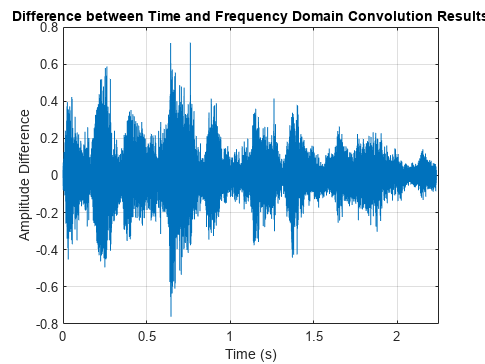


% Plot the difference to visualize any discrepancie
figure;
plot(t, filteredAudio - FilteredAudio_FFT);
xlabel('Time (s)');
ylabel('Amplitude Difference');
title('Difference between Time and Frequency Domain Convolution Results');
grid on;
xlim([0 2.25])

# Assessment 3B

H00368671

**Task 1:**

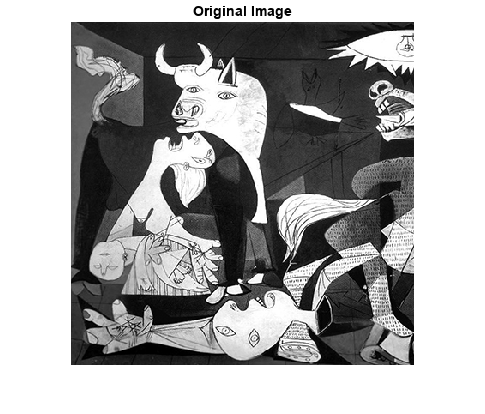

image = imread('guernica_left_bw.jpg'); 

if size(image, 3) == 3
    image = rgb2gray(image);
end

image = double(image);

% Display the original image
figure;
imshow(uint8(image));
title('Original Image');

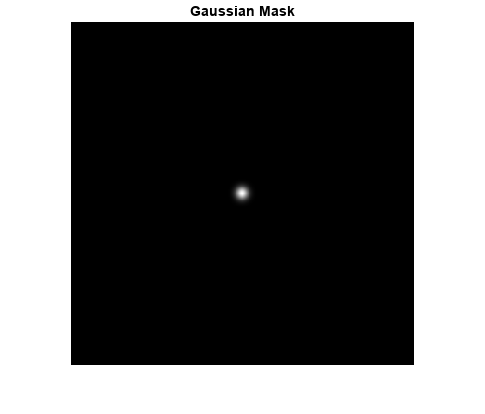


%% Design a Gaussian Mask
[rows, cols] = size(image);
[x, y] = meshgrid(1:cols, 1:rows);

% Center coordinates
x0 = cols / 2;
y0 = rows / 2;

% Standard deviation 
sigma = 5;

% Define the Gaussian mask
gaussian_mask = exp(-((x - x0).^2 + (y - y0).^2) / (2 * sigma^2));

% Normalize the Gaussian mask so that its sum equals 1
gaussian_mask = gaussian_mask / sum(gaussian_mask(:));

% Display the Gaussian mask
figure;
imshow(gaussian_mask, []);
title('Gaussian Mask');

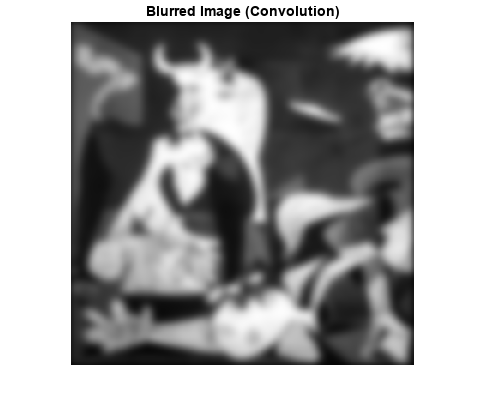


tic; 
blurred_image_conv = conv2(image, gaussian_mask, 'same');
time_conv = toc; 

% Display the blurred image obtained from convolution
figure;
imshow(uint8(blurred_image_conv));
title('Blurred Image (Convolution)');

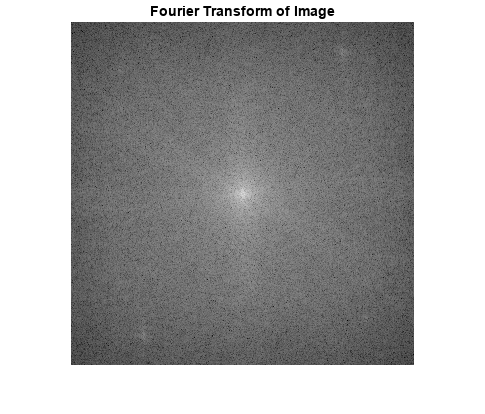


%% Use the Convolution Theorem with 2D Fourier Transforms
tic; 
F_image = fft2(image);

% Compute the Fourier transform of the Gaussian mask
F_gaussian = fft2(gaussian_mask, rows, cols);

% Multiply the Fourier transforms 
F_blurred = F_image .* F_gaussian;

% Compute the inverse Fourier transform to get the blurred image
blurred_image_fft = ifft2(F_blurred);

% Take the real part of the result
blurred_image_fft = real(blurred_image_fft);
time_fft = toc; 

%% Display the Fourier Transforms and Blurred Image
figure;
imshow(log(abs(fftshift(F_image)) + 1), []);
title('Fourier Transform of Image');

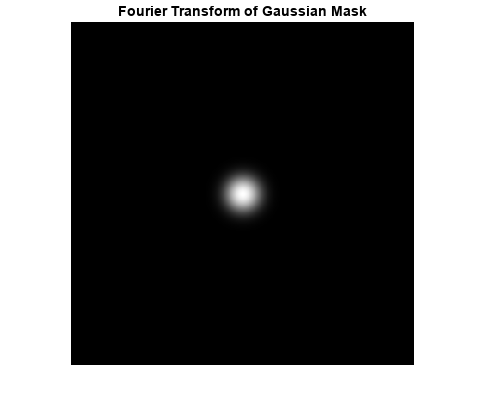


% Display the Fourier Transform of the Gaussian mask
figure;
imshow(log(abs(fftshift(F_gaussian)) + 1), []);
title('Fourier Transform of Gaussian Mask');

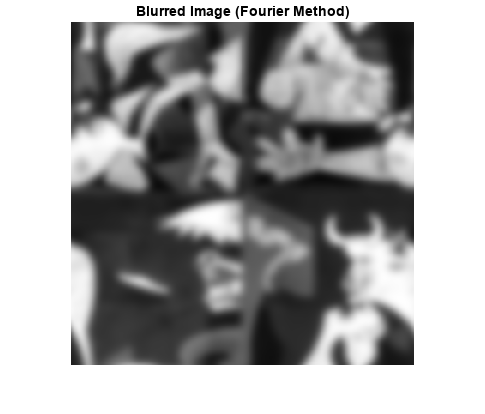


% Display the blurred image obtained from Fourier method
figure;
imshow(uint8(blurred_image_fft));
title('Blurred Image (Fourier Method)');


%% Compare
fprintf('Time taken using conv2(): %f seconds\n', time_conv);

Time taken using conv2(): 1.812737 seconds


fprintf('Time taken using Fourier transforms: %f seconds\n', time_fft);

Time taken using Fourier transforms: 0.023069 seconds



% Compute the difference between the two methods
difference = max(abs(blurred_image_conv(:) - blurred_image_fft(:)));
fprintf('Maximum difference between the two methods: %f\n', difference);

Maximum difference between the two methods: 231.291915


**Task 2**

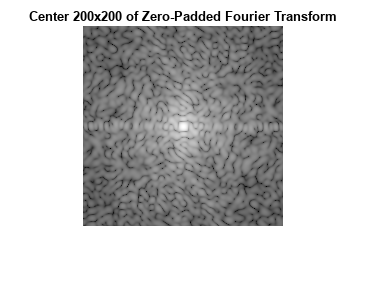

%% Zero-Padded 
pixelsX = 2000;
pixelsY = 2000;

% Perform zero-padded Fourier transform
F_image_padded = fft2(image, pixelsX, pixelsY);

% Shift the zero-frequency component to the center
F_image_padded_shifted = fftshift(F_image_padded);

% Compute the magnitude 
F_image_magnitude = abs(F_image_padded_shifted);

% Extract the center
center_region = 200;
start_index = (pixelsX / 2) - (center_region / 2) + 1;
end_index = (pixelsX / 2) + (center_region / 2);

F_center = F_image_magnitude(start_index:end_index, start_index:end_index);

% Display the center of the Fourier transform
figure;
imshow(log(F_center + 1), []);
title('Center 200x200 of Zero-Padded Fourier Transform');

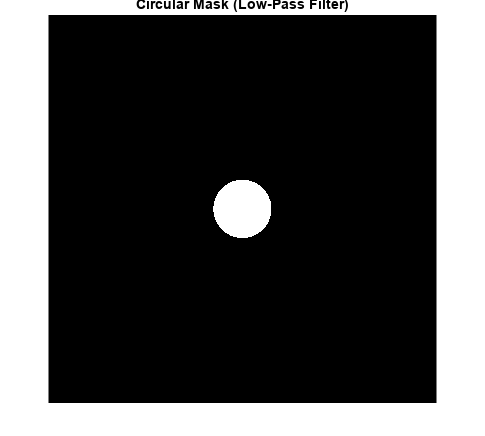


%% Design a Binary Circular Mask
[X, Y] = meshgrid(1:pixelsX, 1:pixelsY);

% Center coordinates
x0 = pixelsX / 2;
y0 = pixelsY / 2;

% Circle radius
radius = 150; 

% Equation of a circle
circle_mask = ((X - x0).^2 + (Y - y0).^2) <= radius^2;

% Display the circular mask
figure;
imshow(circle_mask);
title('Circular Mask (Low-Pass Filter)');

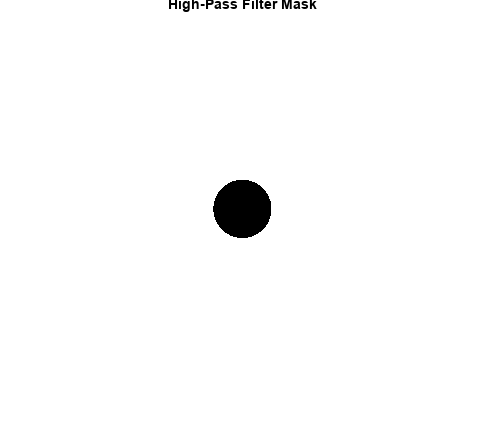


%% Create High-Pass Filter Mask
high_pass_mask = 1 - circle_mask;

% Display the high-pass mask
figure;
imshow(high_pass_mask);
title('High-Pass Filter Mask');

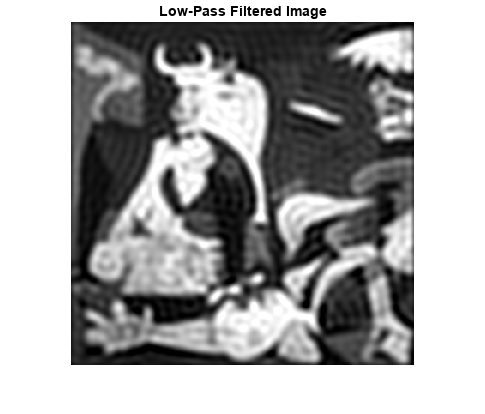


%% Apply Low-Pass Filter
F_low_pass = F_image_padded_shifted .* circle_mask;

% Inverse Fourier Transform to get the low-pass filtered image
low_pass_image = ifft2(ifftshift(F_low_pass));

% Take the real part
low_pass_image = real(low_pass_image);

% Remove zero-padding for plotting
low_pass_image_cropped = low_pass_image(1:size(image,1), 1:size(image,2));

% Display the low-pass filtered image
figure;
imshow(uint8(low_pass_image_cropped));
title('Low-Pass Filtered Image');

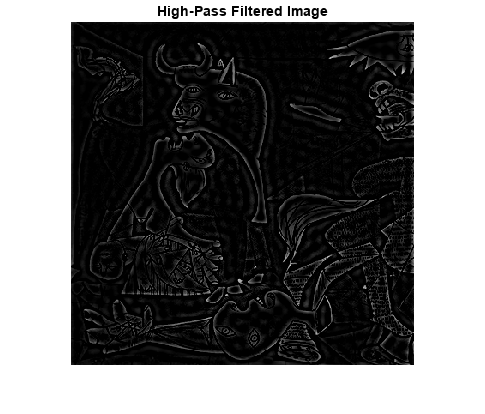


%% Apply High-Pass Filter
F_high_pass = F_image_padded_shifted .* high_pass_mask;

% Inverse Fourier Transform to get the high-pass filtered image
high_pass_image = ifft2(ifftshift(F_high_pass));

% Take the real part
high_pass_image = real(high_pass_image);

% Remove zero-padding for plotting
high_pass_image_cropped = high_pass_image(1:size(image,1), 1:size(image,2));

% Display the high-pass filtered image
figure;
imshow(uint8(high_pass_image_cropped));
title('High-Pass Filtered Image');